% (x+y-1)*dx+(exp(y)+x)*dy=0

clear
% 1)
syms x y(x) C
% y'=-(x+y-1)/(exp(y)+x)
eqn=diff(y(x))==-(x+y-1)/(exp(y)+x)

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{x+y\left(x\right)-1}{x+{\mathrm{e}}^{y\left(x\right)}}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(\frac{x^{2}}{2}+\left(y-1\right)\,x+C_{27}+{\mathrm{e}}^{y},y\right)$$

% solve(exp(y) + x*(y - 1) == - x^2/2 - C12, y)
% exp(y) + x*(y - 1) == - x^2/2 - C12
eq1= exp(y) + x^2/2 + x*y - x == C

$$eq1(x) = {\mathrm{e}}^{y\left(x\right)}-x+x\,y\left(x\right)+\frac{x^{2}}{2}=C$$

% 2)
syms x y dx dy C
eq1=(x+y-1)*dx+(exp(y)+x)*dy

$$eq1 = \mathrm{dx}\,\left(x+y-1\right)+\mathrm{dy}\,\left(x+{\mathrm{e}}^{y}\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} x+y-1 & x+{\mathrm{e}}^{y} \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = x+y-1$$

$$Q = x+{\mathrm{e}}^{y}$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
U=int(P,x,0,x)+int(Q,y,0,y)

$$U = {\mathrm{e}}^{y}+x\,y+x\,\left(y-1\right)+\frac{x^{2}}{2}-1$$

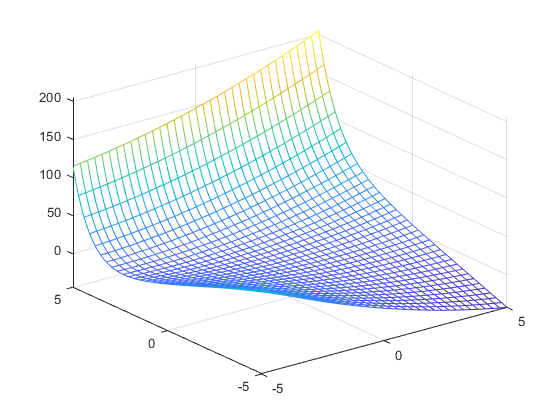

% x^2/2 + (y - 1)*x + exp(y) - 1
% exp(y) + x^2/2 + y*x - x == C
fmesh(U)


% 3)
x0=0;y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = \frac{x^{2}}{2}+\left(y-1\right)\,x+{\mathrm{e}}^{y}-1$$

syms C
eq2=U+1==C

$$eq2 = \frac{x^{2}}{2}+\left(y-1\right)\,x+{\mathrm{e}}^{y}=C$$